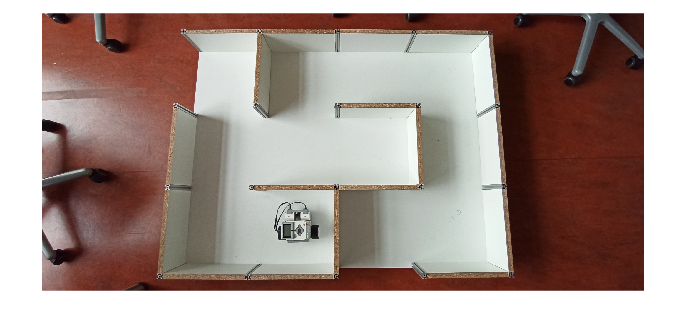

img = imread("maz3.jpg");

figure
imshow(img)

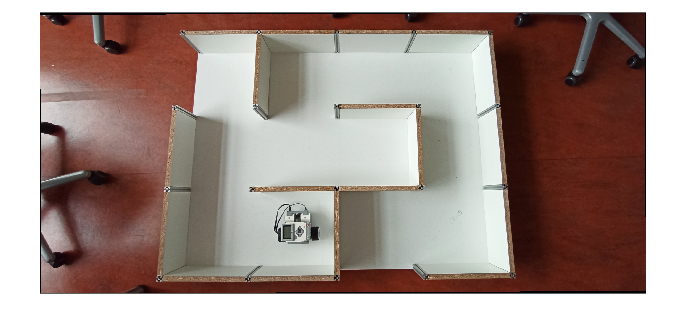


movingPoints=[760 80; 2440 90; 2560 1440; 620 1440;];
fixedPoints=[620 80; 2560 80; 2560 1440; 620 1440;];
tform = fitgeotrans(movingPoints, fixedPoints, "nonreflectivesimilarity");
img_warped = imwarp(img, tform);
imshow(img_warped)

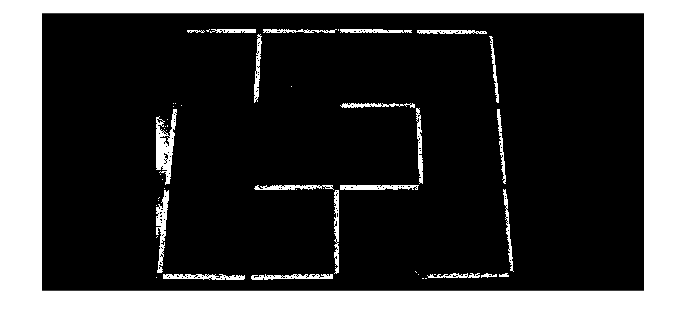


imgRed =  img(:,:,1);
imgGreen = img(:,:,2);
imgBlue = img (:,:,3);

imgBin = imgRed < imgGreen*1.5 & imgBlue * 1.35 < imgRed &  ;
imgBin(:, 1:620) = 0;
imshow(imgBin)